## nirs.modules.TrimBaseline

This module removes excessive baseline at the begining or end of the file. 

**Example Usage (1): **

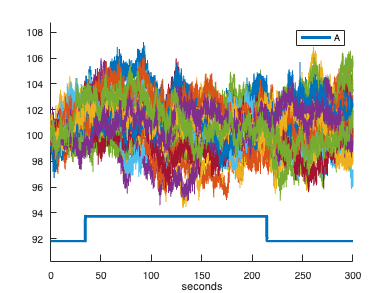

raw = nirs.testing.simData([], @(t)nirs.testing.blockedStimDesign(t,180,50,1));

raw.draw

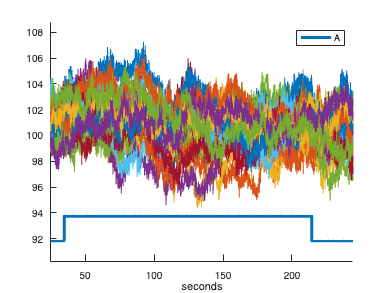


job = nirs.modules.TrimBaseline();
job.preBaseline = 10;
job.postBaseline = 30;
raw = job.run(raw);

figure; raw.draw